clc;clear all;close all;
%%1er paso setear el problema
syms x [3 1]
syms u [3 1]
syms ud [3 1]
syms t

%hallar el X deseado "xd"
xd = [0.01, 2.02, 2.01]';
SS = solve(sate(t,xd,ud) == 0,ud)

SS = struct with fields:
    ud1: -81204/5
    ud2: 201/2
    ud3: -101/5


ud = double([SS.ud1;SS.ud2;SS.ud3])

ud = 1.0e+04 *

   -1.6241
    0.0100
   -0.0020



%2nd paso linealizar
f = sate(t,x,u)

$$f = \left(\begin{array}{c} \frac{u_{1}}{6000}+\frac{2\,x_{2}\,x_{3}}{3}\\ \frac{u_{2}}{7000}-\frac{5\,x_{1}\,x_{3}}{7}\\ \frac{u_{3}}{11000}+\frac{x_{1}\,x_{2}}{11} \end{array}\right)$$

Ajac=jacobian(f,x);
A=double(subs(Ajac,[x;u],[xd;ud]))

A =          0    1.3400    1.3467
   -1.4357         0   -0.0071
    0.1836    0.0009         0


Bjac=jacobian(f,u);
B=double(subs(Bjac,[x;u],[xd;ud]))

B = 1.0e-03 *

    0.1667         0         0
         0    0.1429         0
         0         0    0.0909


rank(ctrb(A,B))%=3 controlable

ans = 3


%3er Paso Aplicar un controlador
%LQR
Q=diag([1000 1000 1000]);
R=0.0001;
K=lqr(A,B,Q,R)

K = 1.0e+03 *

    3.4825    0.0659    2.0481
    0.0564    2.8957    2.5833
    1.1171    1.6439    5.6543


eig(A-B*K)

ans =   -0.5448 + 1.3337i
  -0.5448 - 1.3337i
  -0.4185 + 0.0000i



%simular no lineal ODE45
x0=[0;0;0]

x0 =      0
     0
     0


[T,X]=ode45(@(t,x)sate(t,x,control(x,K,xd,ud)),[0:0.01:30],x0)

T =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


X =          0         0         0
   -0.0199    0.0159    0.0133
   -0.0397    0.0316    0.0265
   -0.0595    0.0473    0.0397
   -0.0791    0.0628    0.0528
   -0.0987    0.0783    0.0658
   -0.1182    0.0936    0.0788
   -0.1377    0.1089    0.0916
   -0.1570    0.1241    0.1044
   -0.1763    0.1392    0.1171


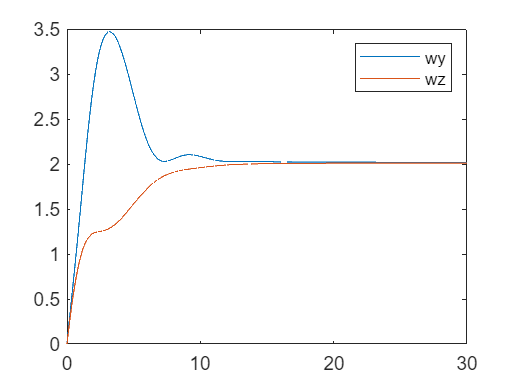

plot(T, X(:, 2:3));
legend('wy','wz')

function u=control(x,K,xd,ud)
    u = ud-K*(x-xd);
end
function dx = sate(t,x,u)
    Ixx=6000;
    Iyy=7000;
    Izz=11000;
    dx=[ u(1)*Ixx^-1-(Iyy-Izz)/Ixx*x(2)*x(3);
         u(2)*Iyy^-1-(Izz-Ixx)/Iyy*x(1)*x(3);
         u(3)*Izz^-1-(Ixx-Iyy)/Izz*x(1)*x(2)  ];
end